doc rlocus

## Example1 : Stable Plant

clear all; close all;
G1=tf([2 5 1],[1 2 3]) % 항상 stable

G1 =
 
  2 s^2 + 5 s + 1
  ---------------
   s^2 + 2 s + 3
 
연속시간 전달 함수입니다.



pole(G1)

ans =   -1.0000 + 1.4142i
  -1.0000 - 1.4142i


zero(G1)

ans =    -2.2808
   -0.2192


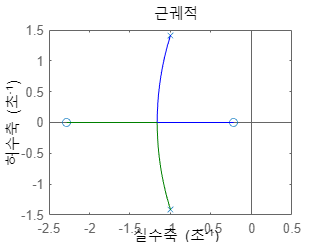

rlocus(G1) % 명령창에서 실행해야 세부 정보 확인 가능

feedback(G1,0.468) % K = 0.468 feedback system

ans =
 
                     
      2 s^2 + 5 s + 1
                     
  ------------------------
                          
  1.936 s^2 + 4.34 s      
                          
                   + 3.468
                          
 
연속시간 전달 함수입니다.



pole(feedback(G1,0.468))

ans =   -1.1209 + 0.7314i
  -1.1209 - 0.7314i


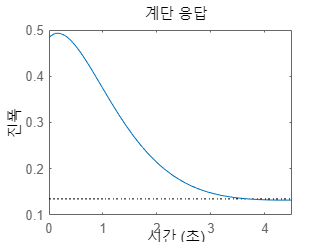

step(feedback(0.468*G1,1)) % K = 0.468 feedback system + step

## Example2 : Unstable Plant

s=tf('s');
G2=(s+1)/s/(s-3) % K가 작을 때 unstable

G2 =
 
    s + 1
  ---------
  s^2 - 3 s
 
연속시간 전달 함수입니다.



pole(G2)

ans =      0
     3


zero(G2)

ans = -1

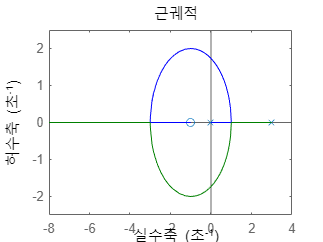

rlocus(G2)

feedback(G2,9)

ans =
 
      s + 1
  -------------
  s^2 + 6 s + 9
 
연속시간 전달 함수입니다.



pole(feedback(G2,9))

ans =   -3.0000 + 0.0000i
  -3.0000 - 0.0000i


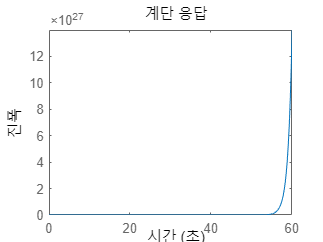

step(feedback(G2,1)) % K = 1 feedback system

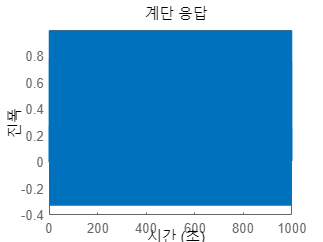

step(feedback(G2,3)) % K = 3 feedback system

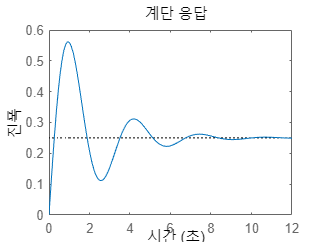

step(feedback(G2,4)) % K = 4 feedback system

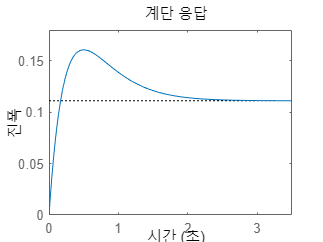

step(feedback(G2,9)) % K = 9 feedback system

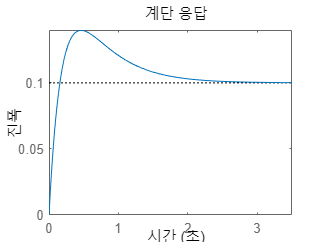

step(feedback(G2,10)) % K = 10 feedback system

## Example3 : Conditional Stable Plant

s=tf('s');
G3=(s^2+2*s+4)/(s*(s+3)*(s+6)*(s^2+1.4*s+1)) % K가 클때 unstable

G3 =
 
                    
       s^2 + 2 s + 4
                    
  ------------------------
                          
  s^5 + 10.4 s^4          
                          
          + 31.6 s^3      
                          
          + 34.2 s^2      
                          
                    + 18 s
                          
 
연속시간 전달 함수입니다.



pole(G3)

ans =    0.0000 + 0.0000i
  -6.0000 + 0.0000i
  -3.0000 + 0.0000i
  -0.7000 + 0.7141i
  -0.7000 - 0.7141i


zero(G3)

ans =   -1.0000 + 1.7321i
  -1.0000 - 1.7321i


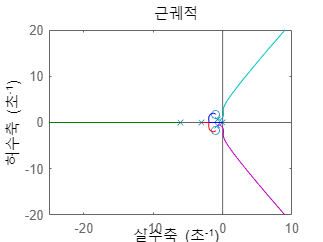

rlocus(G3)

## Control Designer

controlSystemDesigner('rlocus',G3);